# **Miniprojekt C**

## **Formål**

Fra opgavevejledning:

*"Lav i Matlab et system til identifikation af DTMF signaler. Systemet skal kunne reducere forstyrrende elementer i målingen, herunder baggrundsstøj og ”fremmede” enkeltstående frekvenser, - samt fjerne en evt. DC-forskydning.Det er væsentligt, at amplituden på de korrekte frekvenser i signalet ikke ændres nævneværdigt i filtreringsprocesserne."*

*"Der skal i opgaven indgå filtre af begge typer (FIR og IIR), og mindst ét af FIR-filtrene skal designes manuelt vha. vinduesmetoden. Ellers er fir1.m, fir2.m og butter.m i Matlab gode bud på filterdesignfunktioner."*

## **Implementation**

Hver opgave indeholder introduktion, implementation, resultater og diskussion. Resultater er vist under de grå kode blokke.

### P3.13

***Design et 6. ordens båndpas IIR filter (Butterworth). Pasbånd mellem 3kHz og 4kHz, og fs = 24 kHz. Plot og diskuter filterets fasekarakteristik. Bestem filterets group delay (GPD). Plot og diskuter: Hvad sker der ved filtrerets knækfrekvenser? Hvad er max GPD målt i samples, og i millisekunder?***

Vi definere parameterne for vores båndpasfilter. Derefter bruger variablerne til at designe et båndpas IIR filter vha. **designfilt **funktionen. Vi kan nu plotte frekvens- og fase karakteristik samt groupdelay med **fvtool **funktionen:

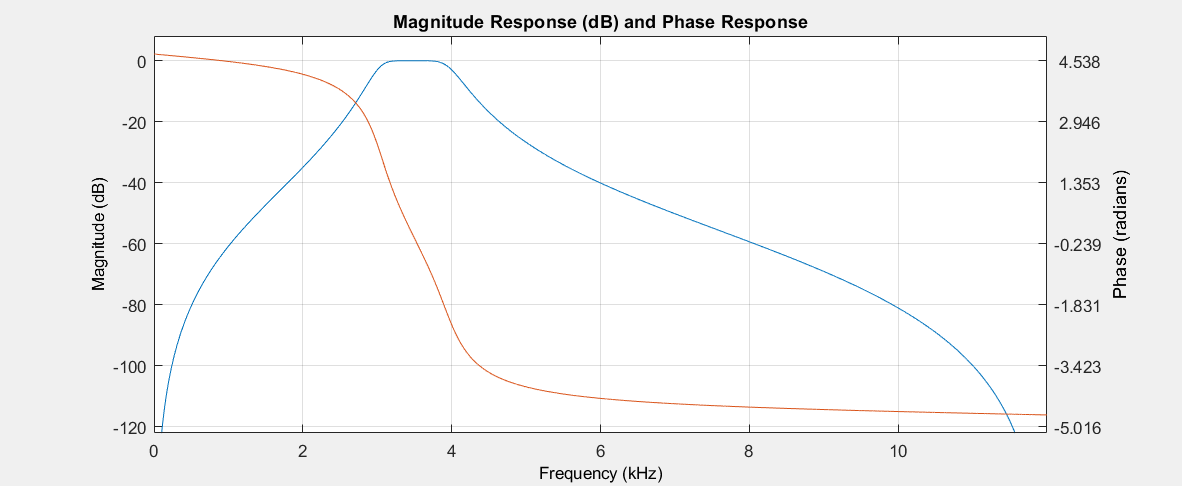

o = 6; % order
fc1 = 3000; % cutoff freq 1
fc2 = 4000; % cutoff freq 2
fs = 24000; % freq. sample

% design butterworth filter
d = designfilt( ...
    'bandpassiir', ... % bandpass
    'FilterOrder', o, ... % order
    'HalfPowerFrequency1', fc1, ... % cutoff freq 1
    'HalfPowerFrequency2', fc2, ... % cutoff freq 2
    'SampleRate', fs ... % freq sample
);

figure(1)
fvtool(d, "Analysis", "freq") % magnitude char. and phase char.

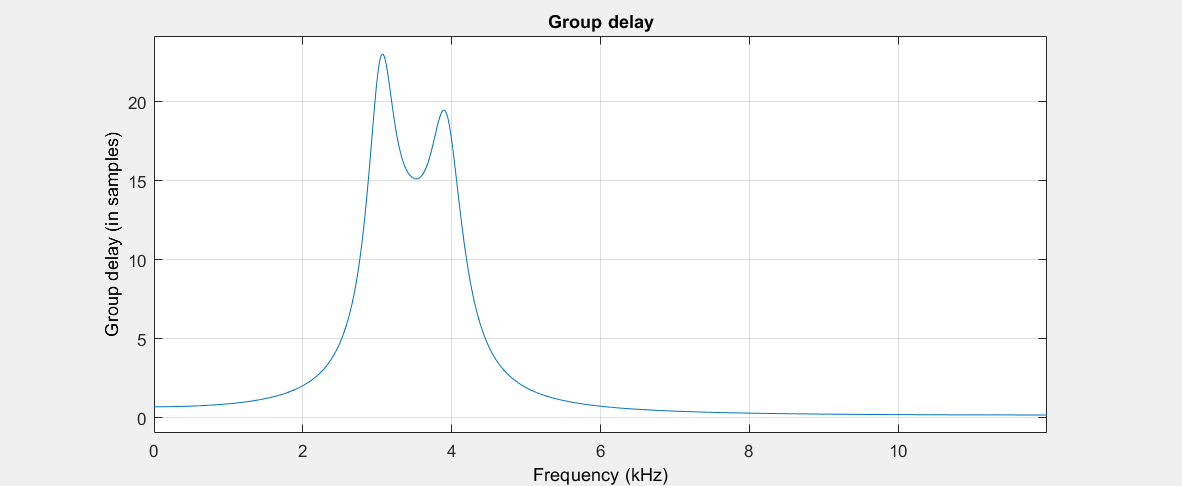

figure(2)
fvtool(d, "Analysis", "grpdelay") % group delay

legend()



### P3.14

***Givet det analoge shelving filter beskrevet som Laplace overføringsfunktion nedenfor:***

- ***Bestem vha. bilineær transformation (substitution) den ækvivalente overføringsfunktion H(z)***

- ***Udregn henholdsvis b og a koefficienterne for H(z). Sampletiden Ts sættes til 1 millisekund,  og vinkelfrekvenserne ω1 = 565 rad/s og ω2 = 942 rad/s.***

- ***Vis frekvensresponsen for H(z) vha. ’freqz’  i Matlab.***

- ***Er H(z) filteret stabilt? Motiver hvorfor eller hvorfor ikke.***

- ***Find differensligningen der repræsenterer H(z), altså y(n) = ...***

**Opgave 1**

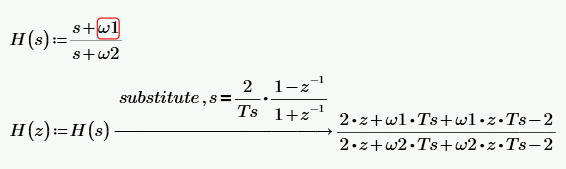

**Opgave 2**

a = [2942 -1058];
b = [2565 -1435];

**Opgave 3**

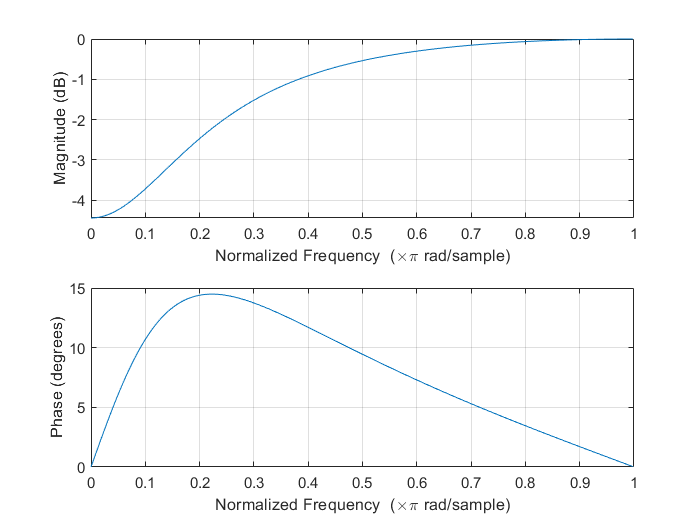

figure(3)
freqz(b, a)

**Opgave 4**

Vi laver et pol-nulpunktsdiagram med **zplane** funktionen:

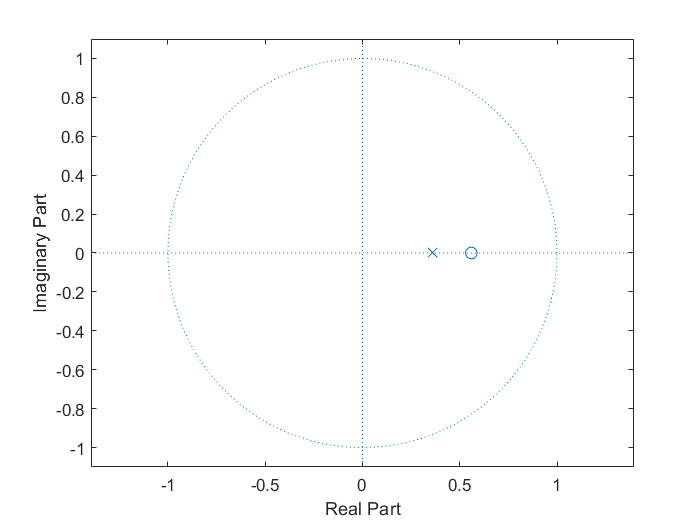

figure(4)
zplane(b, a)

Det ses at poler ligger inde i enhedscirklen, hvilket gør filteret stabilt.

**Opgave 5**

Standardformen for differentialligningen ses på ligning 1 nedenunder. 

For at kunne isolere y(n), divideres hvert koefficient i a og b med 2942. z-ledet i tælleren bliver derved 1. Dvs. a1 ledet bliver det y(n) er, som vi isolere på venstre side. 

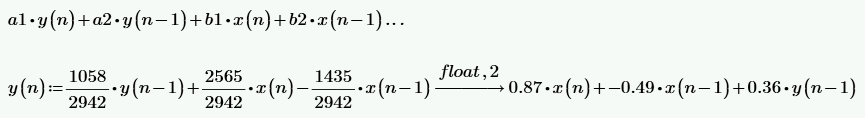

### P3.15

***Plot de første 100 samples af impulsresponsen for et højpas IIR filter (Butterworth) med normeret knækfrekvens 0,05 og ordenen sat til henholdsvis 4 og 12. Plot også pol/nulpunkt-placeringerne (’zplane’).***

**Impuls respons:**

Vi havde ikke held med at bruge designfit funktionen til at lave impulsrespons, så vi har i stedet brugt **butter **funktionen til at lave impulsrespons til de to højpas filtrer. Butter tager 3 paramtre: ordrer, knækfrekvens og filtertypen. Den returnere a og b koefficienterne som vi filtrere med filter og zeroes funktionerne for kun at få 100 samples. Det filtrerede signal plottes med plot.

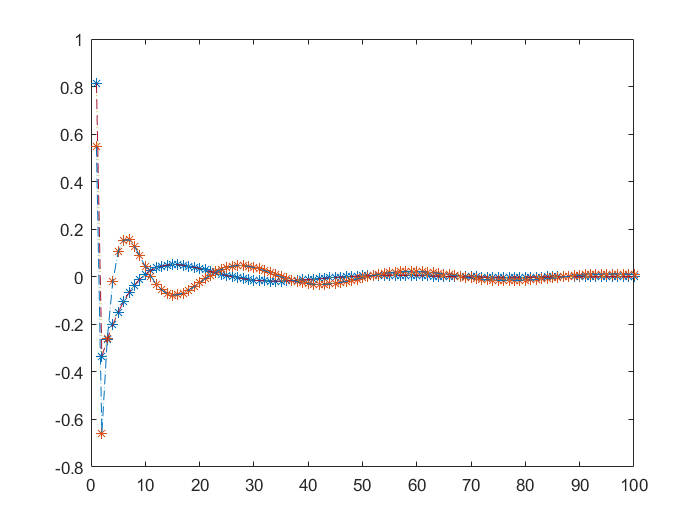

[b1, a1] = butter(4, 0.05, 'high');
impulse = filter(b1, a1, [1 zeros(1,99)]);
figure(5)
plot(impulse,':')

hold on

[b2, a2] = butter(12, 0.05, 'high');
impulse = filter(b2, a2, [1 zeros(1,99)]);
plot(impulse,':')

**Nulpunktsdiagram:**

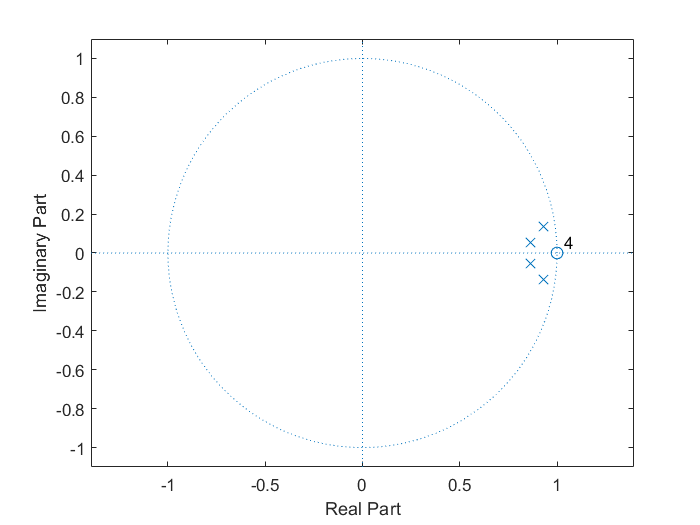

figure(6)
zplane(b1,a1)

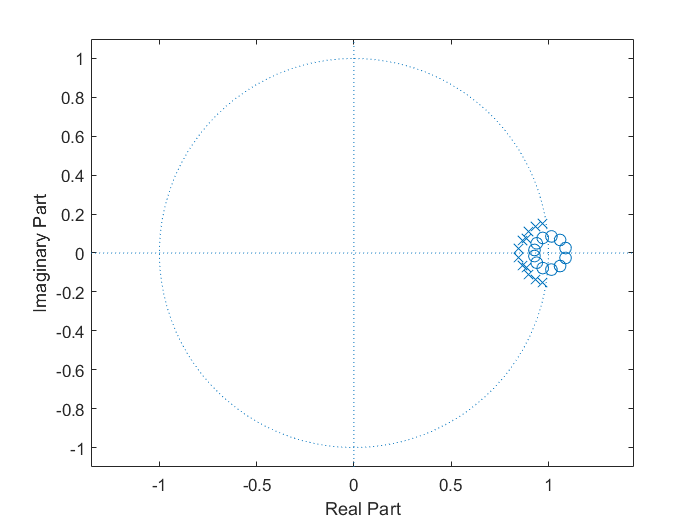

figure(7)
zplane(b2,a2)

### **Opgave 1**

***"Studer og dokumenter DTMF princippet og relevante frekvenser."***

**DTMF** står for **d**ual-**t**one **m**ulti-**f**reqency signaling, og er essentielt et data overføringsystem, der benytter sig af toner med 2 forskellige frekvenser. Det generalle princip er, at man indtaster et nummer, som bliver opfanget, og derved er dit opkald blivet til en dataterminal. Valget af 2 forskellige frekvenser for 1 tone, skyldes man ikke ville have at mennesker kunne imitere tonen. Hvis man f.eks benyttede sig af toner med enkelte frekvenser, kunne det lade sig gøre at ændre destinationen af dit opkald bare ved at fløjte ind i telefonen, mens du indtastede nummeret på din telefon.

**Valg af filtre.**

nedenfor kan ses keypad frekvenser, som går fra sin laveste frekvens, 697 Hz til sin højeste frekvens på 1633.

Ud fra dette kan de dedukteres at vi skal have lavet en lavpasfilter til at filtrere alle frekvenser højere end 1633 fra, et højpasfilter der kan filtrere alle frekvenser lavere end 697 fra, og 8 båndstopsfiltre til at filtrere alle frekvenserne mellem de 9 DTMF frekvenserne fra.

En anden løsning ville også være, lidt som den første, et lavpasfilter, et højpasfilter, og istedet for 8 båndstopsfiltre, så anvendes et enkelt multibåndstopsfilter.

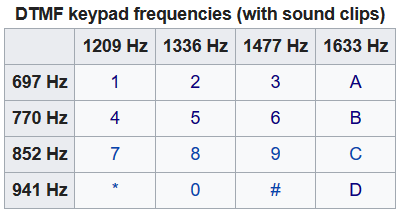

### **Opgave 2**

***"Design og realiser digitale filtre til håndtering af ovennævnte støjproblematikker. Det forventes, at der benyttes forskellige typer filtre til de enkelte opgaver." ***

***Design af lavpas filter vha. af vinduesmetoden.***

clc;
clear;
fs = 16000; %opgavens opgivet sample frekvens.

*Design af lavpasfilter vha. Vindues metoden*

*1.    "Fastlæg knækfrekvens"*

f_cut = 1209; % Valgte knækfrekvens.

*2.    "Fastlæg antal filterkoefficienter 'M'"*

M = 800; % Valgte orden for nu.

*Med disse 3 informationer kan vi også determinere frekvensopløsningen, også kendt som f_delta.*

f_delta = fs/M;

*3.    "Bestem bin-nummer 'm' for ønsket knækfrekvens"*

f_bin = round(f_cut/f_delta); % udregning af bins
f_cut_confirm = f_bin * f_delta; % Bekræftelse af beregnet bin nummer - kan være lidt upræcis, og dette skyldes funktionen round, som runder op.

*5.    "Specificer bin-værdier i overføringsfunktionen H(m) for idéelt filter - op til fs/2"*

H_left = [ones(1,f_bin-1) zeros(1,(M/2)-f_bin+1)]; % konstruere venstre side.

*6.    "Konstruer den fulde H(m) ved spejling"*

H_right = fliplr(H_left(2:end)); % Spejling af venstre side
H = [H_left H_right]; % Det komplete spektrum

*7.    "Frembring impulsresponsen"*

f_impuls = fftshift(real(ifft(H)));

*8.    "Multiplicer med vinduesfunktionen"*

w_hanning = hanning(M-1)';
H_win = f_impuls.*w_hanning;

*9.    "Ckeck det resulterende spektrum"*

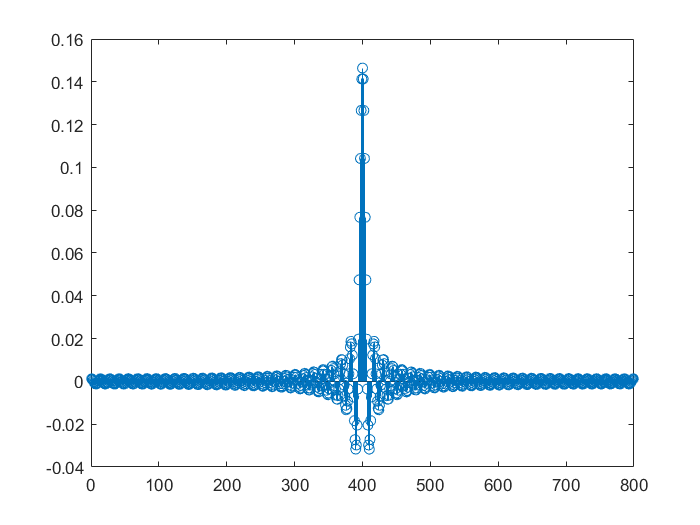

H_win_fft = fft(H_win, fs);
H_Wwin_fft = fft(f_impuls, fs);

figure(1); clf
stem(f_impuls)

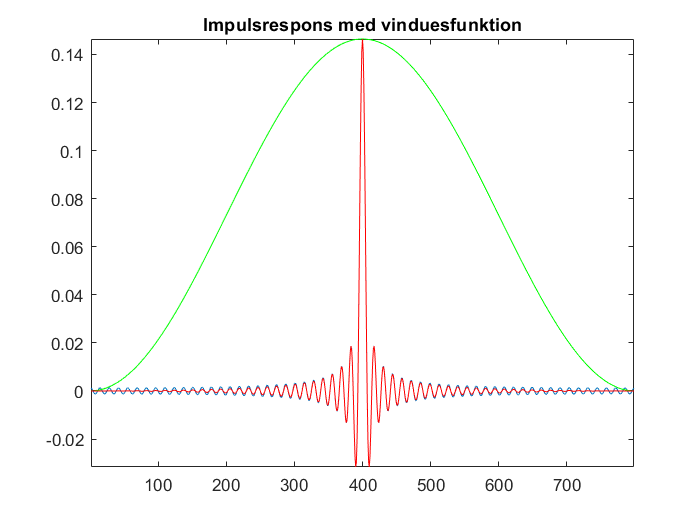


figure(2); clf
plot(f_impuls)
axis([1 M-1 -inf inf])
hold on
plot(w_hanning*max(abs(f_impuls)),'g')
plot(H_win,'r')
title('Impulsrespons med vinduesfunktion')

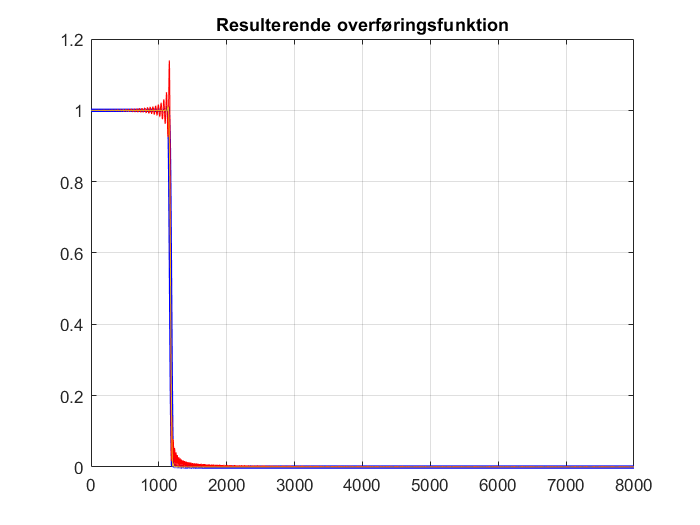


figure(3); clf
plot(abs(H_win_fft(1:fs/2)),'b','linewidth',2)
hold on;
plot(abs(H_Wwin_fft(1:fs/2)),'r')
plot(abs(H_win_fft(1:fs/2)))
grid on
title('Resulterende overføringsfunktion')

*10.    "Forstør / Formindsk evt. M og gentag."*

M = 200; % Valgte orden for nu.
f_delta = fs/M;
f_bin = round(f_cut/f_delta); % udregning af bins
f_cut_confirm = f_bin * f_delta;
H_left = [ones(1,f_bin-1) zeros(1,(M/2)-f_bin+1)]; 
H_right = fliplr(H_left(2:end)); % Spejling af venstre side
H = [H_left H_right]; % Det komplete spektrum
f_impuls = fftshift(real(ifft(H)));

w_hanning = hanning(M-1)';
H_win = f_impuls.*w_hanning;

H_win_fft = fft(H_win, fs);
H_Wwin_fft = fft(f_impuls, fs);

figure(1); clf
stem(f_impuls)

figure(2); clf
plot(f_impuls)
axis([1 M-1 -inf inf])
hold on
plot(w_hanning*max(abs(f_impuls)),'g')
plot(H_win,'r')
title('Impulsrespons med vinduesfunktion')

figure(3); clf
plot(abs(H_win_fft(1:fs/2)),'b','linewidth',2)
hold on;
plot(abs(H_Wwin_fft(1:fs/2)),'r')
plot(abs(H_win_fft(1:fs/2)))
grid on
title('Resulterende overføringsfunktion')

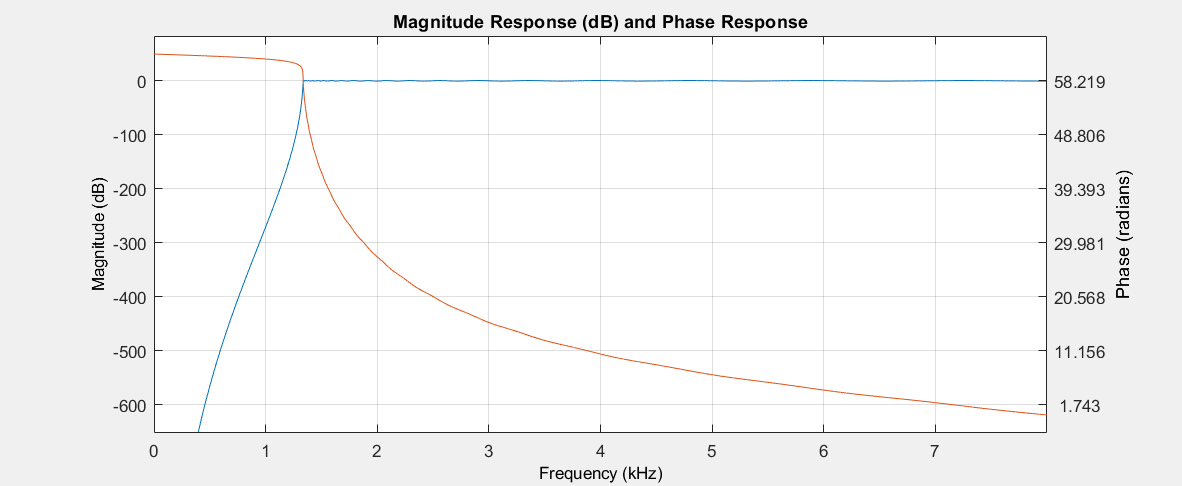


o = 40; % order
fc1 = 1336; % cutoff freq 1
fs = 16000; % freq. sample

hoejpassiir = designfilt( ...
    'highpassiir', ... % bandpass
    'FilterOrder', o, ... % order
    'PassbandFrequency', fc1, ... % cutoff freq 1
    'SampleRate', fs ... % freq sample
);

figure(1)
fvtool(hoejpassiir, "Analysis", "freq"); % magnitude char. and phase char.

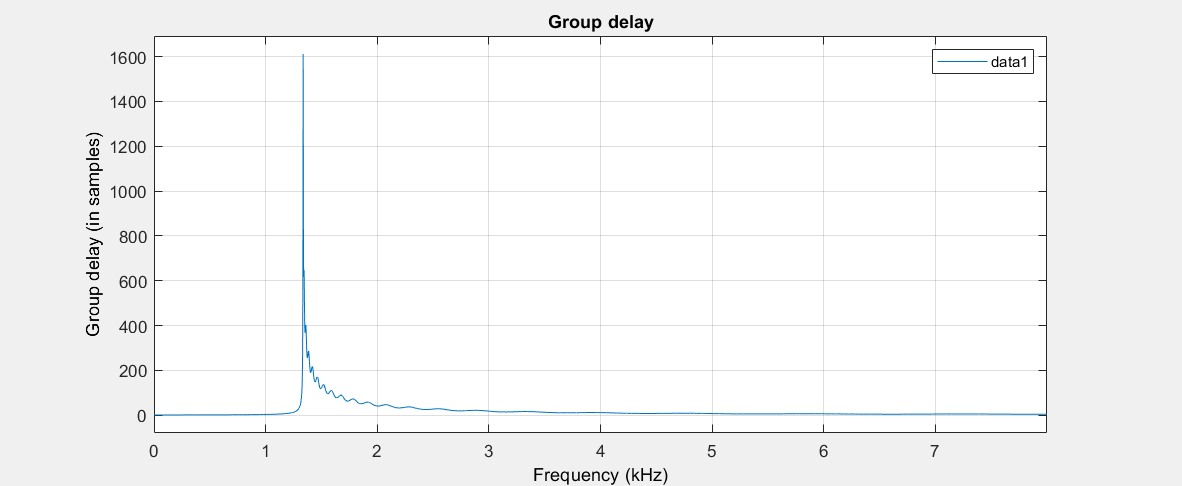

figure(2)
fvtool(hoejpassiir, "Analysis", "grpdelay"); % group delay
legend();

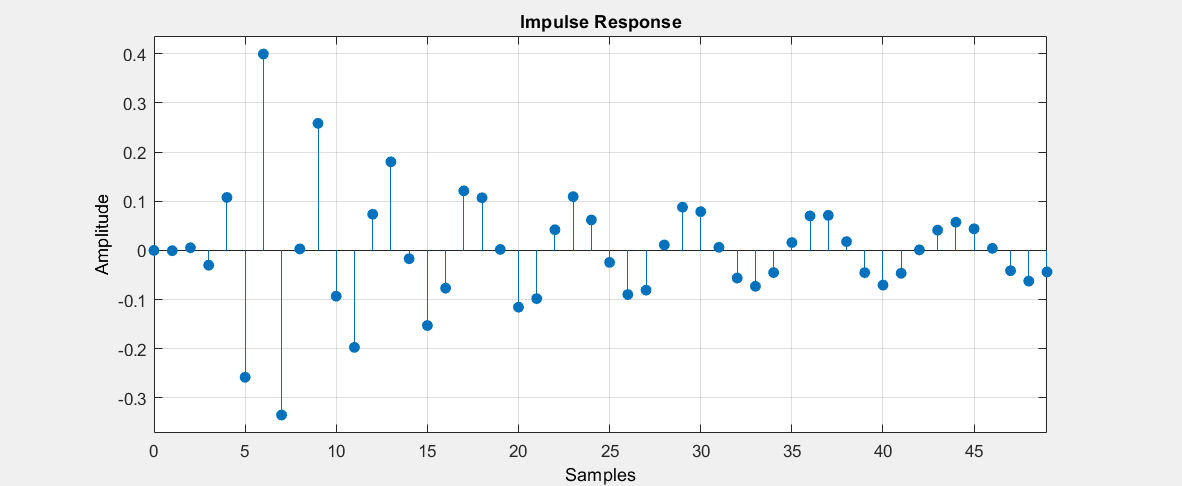

figure(3);
impz(hoejpassiir, 50);

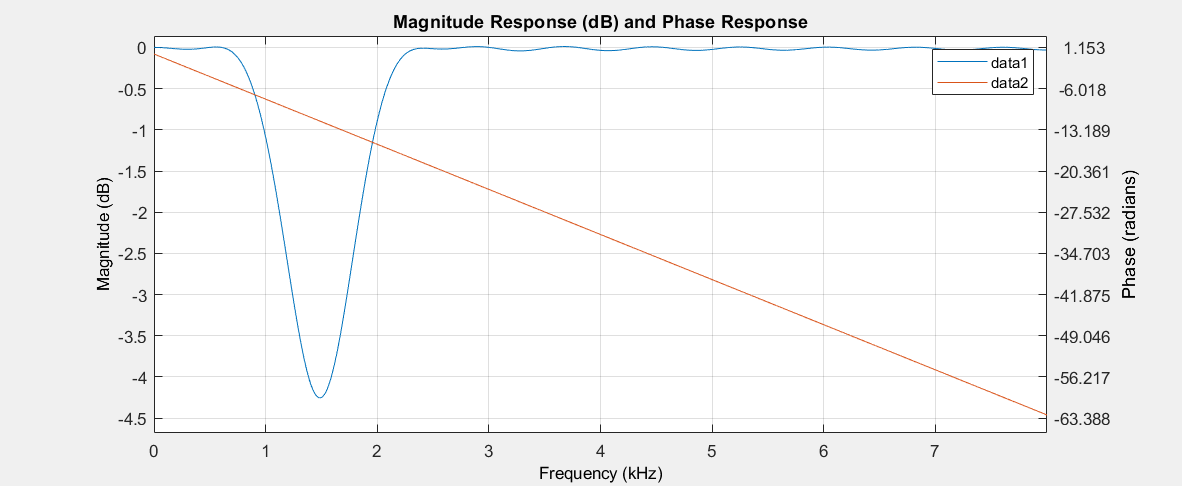

o = 40; % order
fc1 = 1336; % cutoff freq 1
fc2 = 1633; % cutoff freq 2
fs = 16000; % freq. sample

bandstopfir = designfilt( ...
    'bandstopfir', ... % bandpass
    'FilterOrder', o, ... % order
    'cutoffFrequency1', fc1, ... % cutoff freq 1
    'cutoffFrequency2', fc2, ... % cutoff freq 2
    'SampleRate', fs ... % freq sample
);

figure(1);
fvtool(bandstopfir, "Analysis", "freq"); % magnitude char. and phase char.
legend();

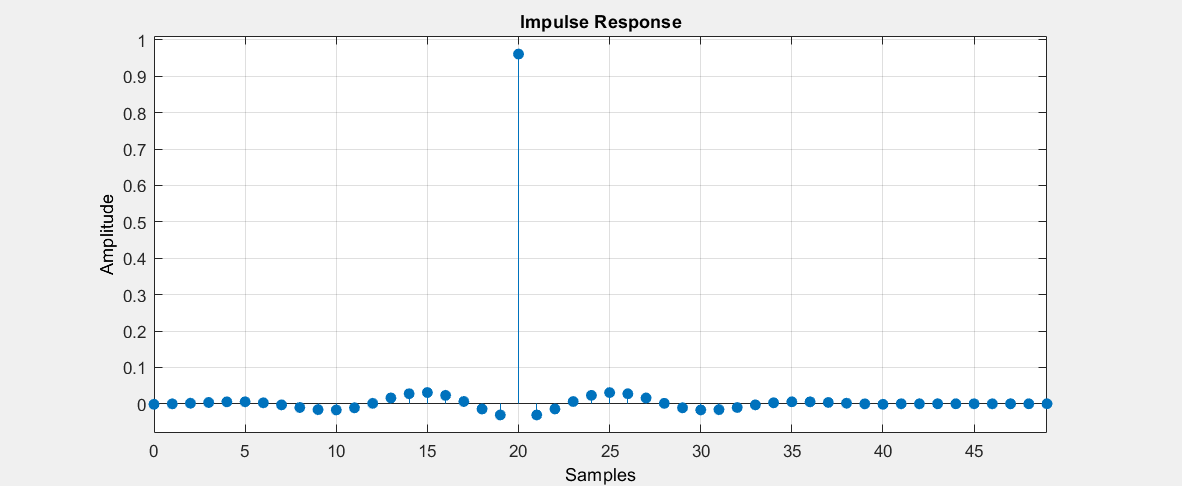

figure(2);
impz(bandstopfir, 50);

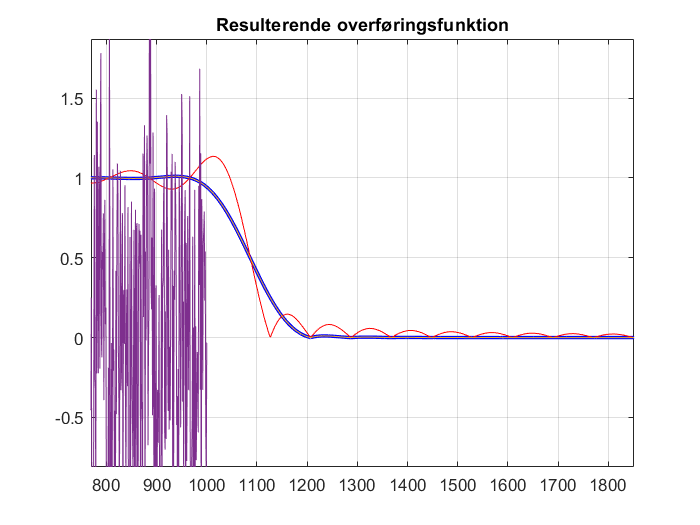


figure(3);
[b, a] = tf(bandstopfir);

data = randn(1000,1);
y = filter(bandstopfir,data);
plot(y);

### **Opgave 3**

***"Eksperimenter i opgaven med forskellige filterordener og afskæringsfrekvenser. Dokumenter eksperimenterne og udvælg de ”bedste”."***

### **Opgave 4**

***"Vis udvalgte filtres impulsrespons h(n) og overføringskarakteristik H(m)."***

### **Opgave 5**

***"Vis for ét af filtrene fasekarakteristikken og group delay. Kommenter."***

### **Fjern DC-offset:**

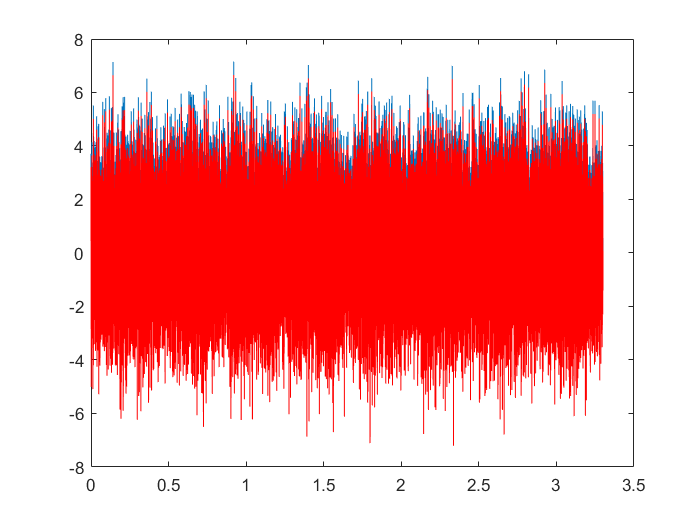

clc
clear
clf
close all;

% loaded file contains freq. sample and the signal
load = load('DTMF_noisy_signal.mat');

% signal variables
fs = load.f_sample; % store fs from load
sig_noisy= load.s_total; % store signal samples from load
n = length(sig_noisy); % length of signal
freq_res = fs / n; % frequency resolution


% time axis
Ts = 1/fs; % time pr. sample
Tn = n * Ts; % total signal play time
t = 0:Ts:Tn-Ts; % time axis; start 0 and step by Ts untill Tn is reached

% dc-offset
dc = mean(sig_noisy); % dc offset / mean value
sig_no_offset = sig_noisy - dc; % remove dc from signal

% plot
plot(t,sig_noisy);
hold on;
plot(t, sig_no_offset, "r");


%soundsc(sig_no_offset, fs);

## **Konklusion**